## Programmierblatt 1

Jonathan Schnitzler

Matr. - Nr: 3465192

Wir betrachten hier verschiedene Verfahren, um Differentialgleichungen zu lösen (Aufgabe 1) und gehen dann über diese Methoden auf Leib und Seele zu testen

### Aufgabe 1

Die Funktionen sind in einem jeweiligen script geschrieben.

### Aufgabe 2 (Räuber-Beute Modell)

%Parameter in struct p
p.alpha = 1;
p.beta = 1;
p.gamma = 1;
p.delta = 1;

%startvalue
y_0 = [0.5;0.5];

%total time
T = 20;

%step size
tau = [0.64, 0.32, 0.16, 0.08, 0.04]

tau =     0.6400    0.3200    0.1600    0.0800    0.0400


%tau = [0.05, 0.025];
%function handle
f =  @lotkaVolterra

f = function_handle with value:
    @lotkaVolterra


Plotten wir zunächst das Phasendiagramm der Lotka-Volterra Gleichung

nElem = 16;
meshX = linspace(0,3,nElem);
meshY = linspace(0,3,nElem);
[X,Y] = meshgrid(meshX,meshY);
U = zeros(nElem,nElem);
V = zeros(nElem,nElem);
for k = 1:nElem
    for l = 1:nElem
        foo = f(p, 0, [meshX(k),meshY(l)]);
        U(k,l) = -foo(2); %Verstehe ich nicht
        V(k,l) = -foo(1);
    end
end
quiver(X,Y,U,V);
hold on

Nun testen wir die in **Aufgabe 1** implementierten Verfahren

`explicit_euler:`

for k = tau
    Y_euler = explicit_euler(f,y_0,T,k,p);
    plot(Y_euler(1,:),Y_euler(2,:));
end

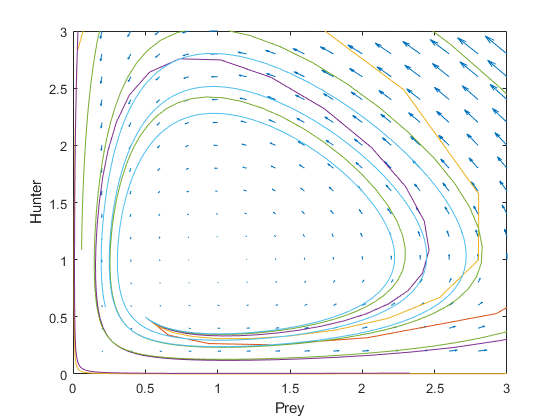

xlabel('Prey')
ylabel('Hunter')
xlim([0 3])
ylim([0 3])
hold off

tau

tau =     0.6400    0.3200    0.1600    0.0800    0.0400


`explicit_heun:`

nElem = 16;
meshX = linspace(0,3,nElem);
meshY = linspace(0,3,nElem);
[X,Y] = meshgrid(meshX,meshY);
U = zeros(nElem,nElem);
V = zeros(nElem,nElem);
for k = 1:nElem
    for l = 1:nElem
        foo = f(p, 0, [meshX(k),meshY(l)]);
        U(k,l) = -foo(2); %Verstehe ich nicht
        V(k,l) = -foo(1);
    end
end
quiver(X,Y,U,V);
hold on
for k = tau
    Y_heun = explicit_heun(f,y_0,T,k,p);
    plot(Y_heun(1,:),Y_heun(2,:));
end

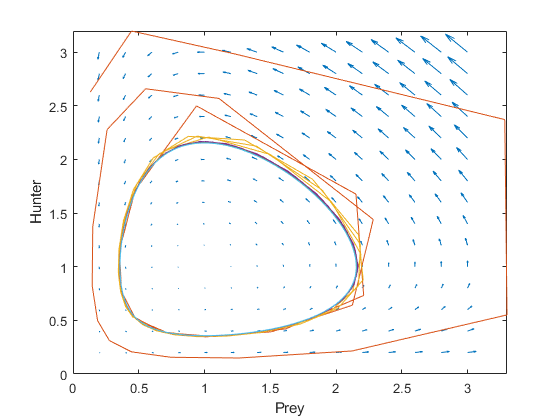

xlabel('Prey')
ylabel('Hunter')
xlim([0 3])
ylim([0 3])
hold off